input_size = 784;  % 28x28
hidden_size = 128; % Выбрано случайное значение
output_size = 11;  % Цифры 0-9

% Количество скрытых слоев
Model.hiden = 1;

% Инициализация первого слоя (ReLU)
Model.W1 = randn(input_size, hidden_size) * sqrt(2/input_size);
Model.b1 = zeros(1, hidden_size);
Model.f1 = @(x) max(0, x);
Model.df1 = @(x) x>0;

% Инициализация второго слоя 
Model.W2 = randn(hidden_size, output_size) * 0.01;  % Малое случайное значение
Model.b2 = zeros(1, output_size);
Model.f2 = @(x) exp(x - max(x, [], 2)) ./ sum(exp(x - max(x, [], 2)), 2);

% 1. Загрузка данных
% [X_train, y_train, X_test, y_test] = load_mnist();

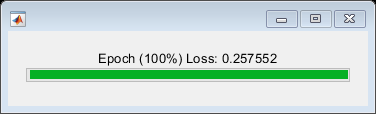

% 2. Обучение
batch_size = 10;
learning_rate = 0.001;
epochs = 2000;
[Model, hist] = train(Model, X_train, y_train, @(x, y) LosFunction(x, y) ,batch_size, learning_rate, epochs);

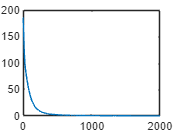

plot(hist)

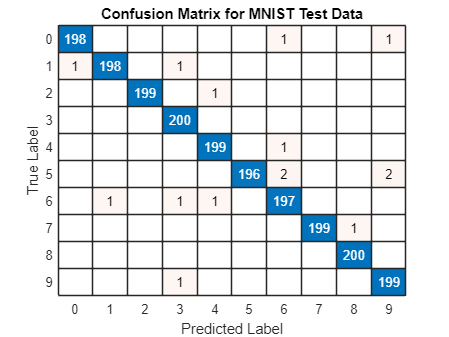

% 3 Предсказание на тестовых данных
[~, hist_test] = forward(Model, X_test);  % Получаем выход последнего слоя
y_pred_prob = hist_test.("F" + int2str(Model.hiden + 1));  % Выход сети (вероятности)
[~, y_pred] = max(y_pred_prob, [], 2);  % Берем индекс максимального значения (метка класса)
y_true = vec2ind(y_test')';  % Преобразуем one-hot обратно в метки

% Вычисление confusion matrix
C = confusionmat(y_true, y_pred);

% Визуализация
figure;
confusionchart(C, string(0:9));  % MNIST: цифры 0-9
title('Confusion Matrix for MNIST Test Data');
xlabel('Predicted Label');
ylabel('True Label');

% Отчет о классификации
stats = confusionmatStats(C);
disp('Classification Report:');

Classification Report:


disp(stats)

     accuracy: 0.9925
    precision: [10×1 double]
       recall: [10×1 double]
           F1: [10×1 double]



function res = LosFunction(y_pred, y_true)
    eps = 1e-15;
    res = mean(-sum(y_true.*log(max(eps, y_pred)), 2));
end

function stats = confusionmatStats(C)
    stats.accuracy = sum(diag(C)) / sum(C(:));
    stats.precision = diag(C) ./ sum(C, 2);
    stats.recall = diag(C) ./ sum(C, 1)';
    stats.F1 = 2 * (stats.precision .* stats.recall) ./ (stats.precision + stats.recall);
end

function [res, his] = forward(Model, input)
    X = input;
    
    for i=1:Model.hiden+1
        hist.("W"+int2str(i)) = X*Model.("W"+int2str(i))+Model.("b"+int2str(i));

        X = Model.("f"+int2str(i))(X*Model.("W"+int2str(i))+Model.("b"+int2str(i)));
        
        hist.("F"+int2str(i)) = X;
    end
    res = X;
    his = hist;
end

function Model = backward(Model, X_batch, y_batch, hist)
    m = size(X_batch, 1); % Количество примеров в батче
    layers = Model.hiden + 1; % Общее количество слоёв
    
    % Инициализация градиента выходного слоя (softmax + cross-entropy)
    dZ = hist.("F"+int2str(Model.hiden + 1)) - y_batch;
    
    % Обратное распространение по слоям
    for i = (Model.hiden + 1):-1:1
        % Получаем активации предыдущего слоя
        if i == 1
            A_prev = X_batch;
        else
            A_prev = hist.("F"+int2str(i-1));
        end
        
        % Сохраняем градиенты в структуру Model
        Model.("dW"+int2str(i)) = (A_prev' * dZ) / m;
        Model.("db"+int2str(i)) = sum(dZ, 1) / m;
        
        % Если не входной слой, вычисляем градиент для предыдущего
        if i > 1
            W = Model.("W"+int2str(i));
            Z = hist.("W"+int2str(i-1));
            dA = dZ * W';
            dZ = dA .* Model.("df"+int2str(i-1))(Z);
        end
    end
end


function [res, train_hist] = train(Model, dataset, y_true, loss_func, batch_size, lr, num_epochs)
    num_samples = size(dataset, 1); % Количество примеров
    num_batches = ceil(num_samples / batch_size); % Количество батчей
    train_hist = [];
    h = waitbar(0, 'Processing...');

    for epoch = 1:num_epochs
        % Перемешивание данных на каждой эпохе
        shuffled_indices = randperm(num_samples);
        shuffled_data = dataset(shuffled_indices,:);
        shuffled_labels = y_true(shuffled_indices,:);
        
        total_epoch_loss = 0;
        for batch=1:num_batches
            % Выделение текущего батча
            start_idx = (batch - 1) * batch_size + 1;
            end_idx = min(batch * batch_size, num_samples);
            X_batch = shuffled_data(start_idx:end_idx, :);
            y_batch = shuffled_labels(start_idx:end_idx, :);
           
            [y_pred, hist] = forward(Model, X_batch); % Прямой проход
            Loss = loss_func(y_pred, y_batch); % Вычисление ошибки на батче
            total_epoch_loss = total_epoch_loss + Loss*length(X_batch);
            Model = backward(Model, X_batch, y_batch, hist); % Обратный проход

            % Коррекция весов
            for i = 1:Model.hiden+1 
                Model.("W"+int2str(i)) = Model.("W"+int2str(i)) - lr * Model.("dW"+int2str(i));
                Model.("b"+int2str(i)) = Model.("b"+int2str(i)) - lr * Model.("db"+int2str(i));
            end
        end
        total_epoch_loss = total_epoch_loss/num_samples;
        train_hist = [train_hist, total_epoch_loss];
        waitbar(epoch/num_epochs, h, sprintf('Epoch (%d%%) Loss: %f',ceil(epoch/num_epochs*100), total_epoch_loss));
        
    end
    res = Model;
end

% требуется Deep Learning Toolbox
function [X_train, y_train, X_test, y_test] = load_mnist()
    
    digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', ...
        'nndatasets', 'DigitDataset');
    imds = imageDatastore(digitDatasetPath, ...
        'IncludeSubfolders', true, 'LabelSource', 'foldernames');
    
    % Разделение на train/test
    [imdsTrain, imdsTest] = splitEachLabel(imds, 0.8, 'randomized');
    
    % Вытягивание в матрицы
    X_train = zeros(numel(imdsTrain.Files), 28*28);
    for i = 1:numel(imdsTrain.Files)
        img = readimage(imdsTrain, i);
        X_train(i,:) = double(img(:))'/255;
    end
    y_train = double(imdsTrain.Labels);
    
    X_test = zeros(numel(imdsTest.Files), 28*28);
    for i = 1:numel(imdsTest.Files)
        img = readimage(imdsTest, i);
        X_test(i,:) = double(img(:))'/255;
    end
    y_test = double(imdsTest.Labels);
    
    % One-hot кодирование
    y_train = ind2vec(y_train' + 1)';
    y_test = ind2vec(y_test' + 1)';
end